## Assignment 1

clc;
close all;
clear variables;

### Loading files

input_file_subfolder = 'data/raw';
intput_file_expension = 'bmp';

input_files = dir(input_file_subfolder + "/" +  "*." + intput_file_expension)

input_files = 600×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


### Example file

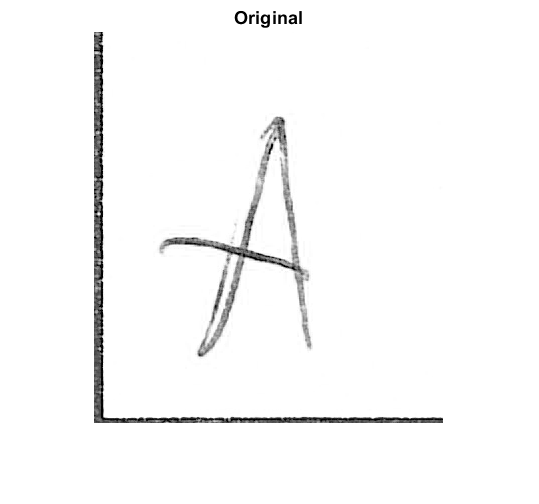

input_file = input_files(1);
file_path = input_file.folder + "\" + input_file.name;
img = imread(file_path);
figure()
imshow(img)
title('Original')

### Preprocessing example

tic
[img_cropped, img_binary] = edge_removal(img);
toc 

Elapsed time is 0.023506 seconds.


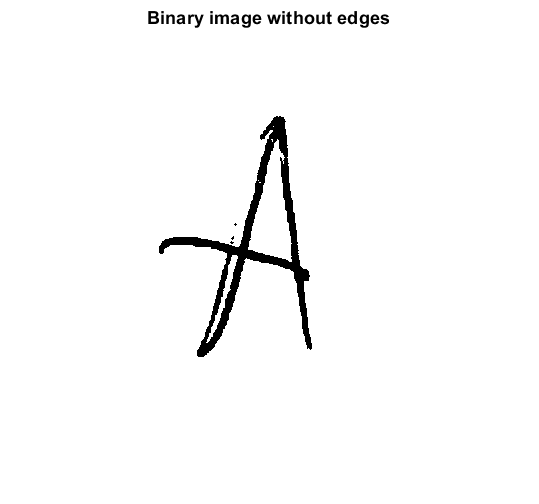


figure()
imshow(img_binary)
title('Binary image without edges')

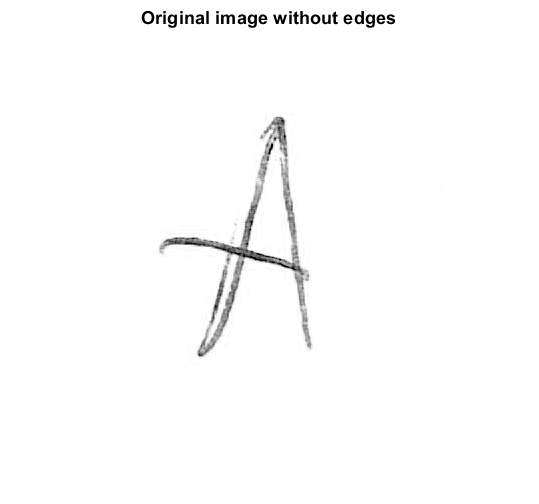


figure()
imshow(img_cropped)
title('Original image without edges')

### Preprocess all

for input_file = input_files(100:100)'

    [img_cropped, img_binary] = edge_removal(imread(input_file.folder + "\" + input_file.name));

end
